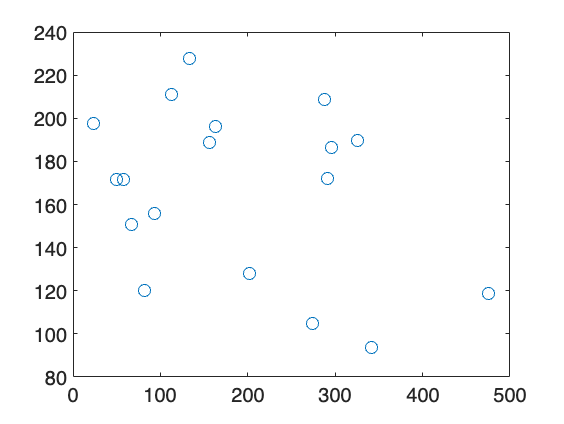

clear
clc
a = csvread('thick2rgb.csv');
x = a(:,1);
ry = a(:,2);
gy = a(:,3);
by = a(:,4);


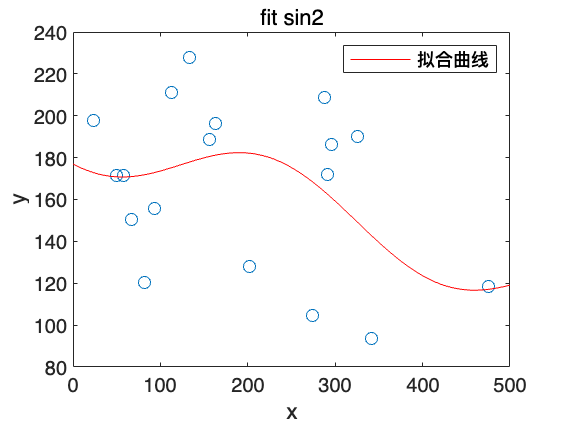

gp = fit(x, gy, 'sin2');
figure
plot(x,gy,'o');
title('fit sin2')
hold on
plot(gp)
hold off

model = @(b, x) b(1)*sin(b(2)*x+b(3))+b(4)*sin(b(5)*x+b(6));
%构造问题对象
problem = createOptimProblem('lsqcurvefit', ...%优化方法
'objective', model, ...%目标函数
'xdata', x, 'ydata', ry, ...%值
'x0',ones(1,6),...%初始试探值
'lb', [-Inf 0 -Inf -Inf 0 -Inf],...%参数下限
'ub', [Inf 0.1 Inf Inf 0.1 Inf]) %参数上限

problem = 包含以下字段的 struct :
    objective: @(b,x)b(1)*sin(b(2)*x+b(3))+b(4)*sin(b(5)*x+b(6))
           x0: [1 1 1 1 1 1]
        xdata: [18×1 double]
        ydata: [18×1 double]
           lb: [-Inf 0 -Inf -Inf 0 -Inf]
           ub: [Inf 0.1000 Inf Inf 0.1000 Inf]
        Aineq: []
        bineq: []
          Aeq: []
          beq: []
      nonlcon: []
       solver: 'lsqcurvefit'
      options: [1×1 optim.options.Lsqcurvefit]


ms = MultiStart;%随机多次优化对象
ms.Display = 'iter';
rng default
[~,fval,exitflag,output,solutions] = run(ms, problem, 100);%尝试50次全局优化

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         0    5.257e+05        85       602         926.9
       2         3    2.468e+05        33       238         52.48
       3         0    3.076e+04        85       602          1367
       4         3    4.256e+05        38       273           214
       5         0    2.881e+05        85       602     3.136e+04
       6         0     3.33e+05        85       602     9.713e+04
       7         0    2.404e+05        85       602     2.247e+04
       8         0    1.642e+06        85       602     7.422e+04
       9         3    2.468e+05        18       133         64.94
      10         0    4.721e+05        85       602     2.919e+04
      11         0    4.743e+05        85       602     2.056e+05
      12         0    3.306e+05        85       602     6.825e+04
      13         0    3.069e+04        85       602          1231
      14  

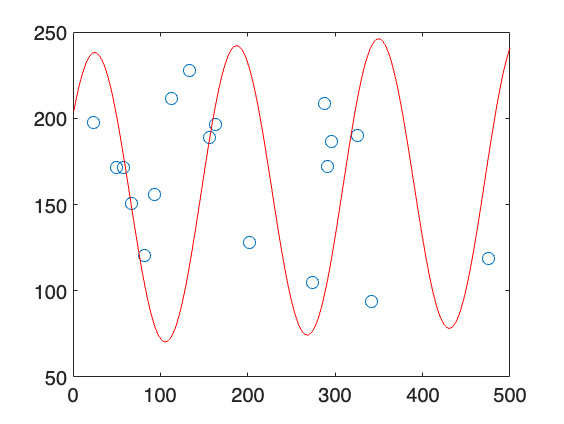

plot(x,gy,'o'), hold on
xx = 1:500;
cc2=model(solutions(1,1).X,xx);
plot(xx,cc2,'r-'),hold off

solutions(1,1).X%最优值的解

ans =   262.3967    0.0001 -263.2731  -84.8576    0.0387 -963.8520


solutions(1,1).Fval%最优值的残差

ans = 3.0672e+04